# Taller: Análisis Tiempo-Frecuencia

**Integrantes:**

- Dayana Valentina Gonzalez Vargas

- David Santiago Flórez Alsina

- Juan Pablo Sierra Useche

% Init. Data
raw = load("./ecg.mat", "-mat");
ecg = raw.ecg;
%fs = raw.samplingrate;
fs = raw.Fs;

t =  linspace(0, fs.^(-1), length(ecg));
winSizes = linspace(0.2/(fs^-1), 5/(fs^-1), 5); 

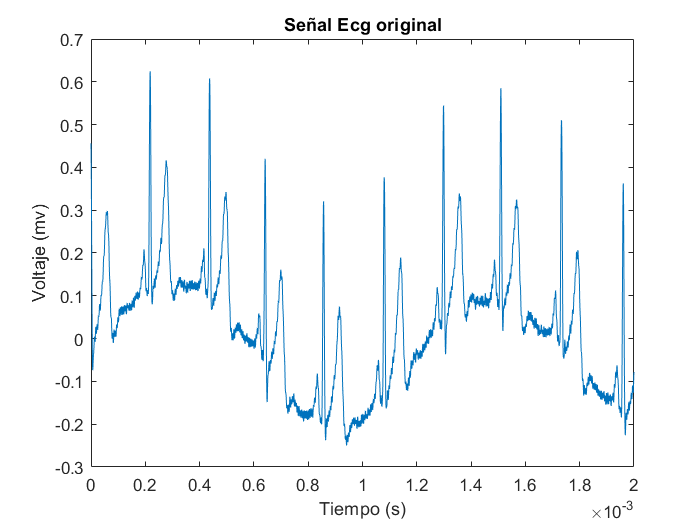

figure
plot(t, ecg)
title("Señal Ecg original");
xlabel("Tiempo (s)")
ylabel("Voltaje (mv)")

## Análisis de las gráficas 

En la ventana más pequeña se puede distinguir mucho más claro la intensidad de las frecuencias que corresponden a los picos en la señal ecg, incusive podría decirse que la magnitud espectral puede parecese a los picos de intensidad de la señal original. Notando que se van acercando las aplitudes mayores de la señal original en donde se relacionan los picos su contendio espectral en una ventana más grande se van atenuando y acercando a un cierto rango de frecuencias más reducido.

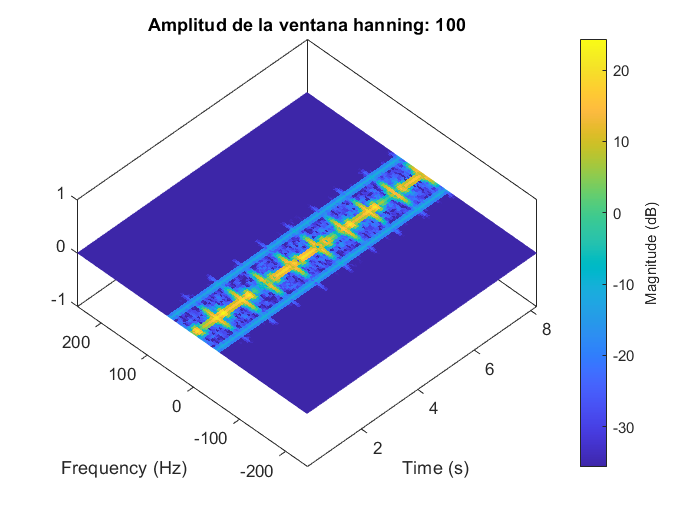

figure
stft(ecg,fs,'Window',hann(winSizes(1)), 'FFTLength', winSizes(1));
title("Amplitud de la ventana hanning: " + string(winSizes(1)));
view(-45,65)

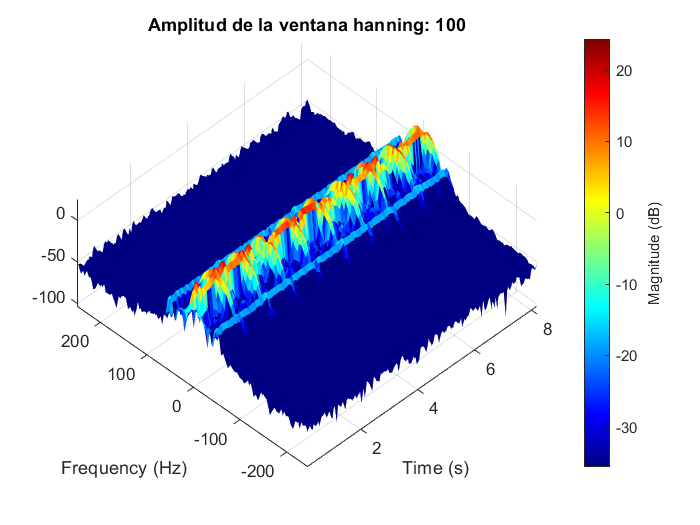

colormap jet

Cuando la ventana va aumentando de tamaño, se deja de ver la tendencia principal de la señal en términos de intensidad.

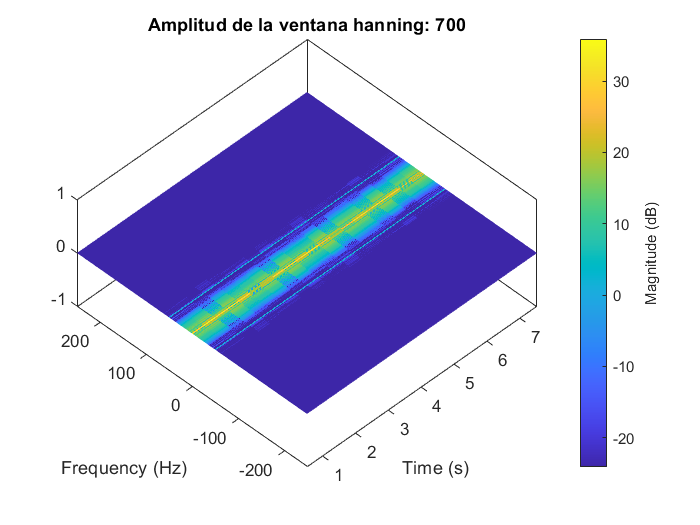

figure
stft(ecg,fs,'Window',hann(winSizes(2)), 'FFTLength', winSizes(2));
title("Amplitud de la ventana hanning: " + string(winSizes(2)));
view(-45,65)

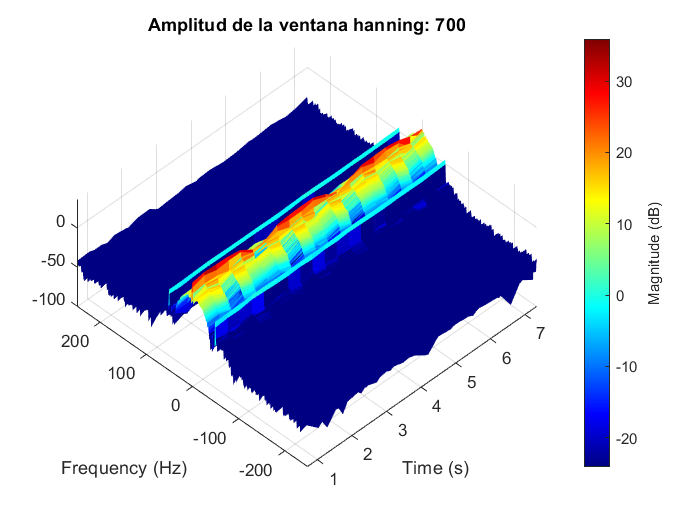

colormap jet

Por otra parte se ve que la amplitud de frecuencias va máximo hasta unos 150 Hz, datos que concuerdan con la documentación. 

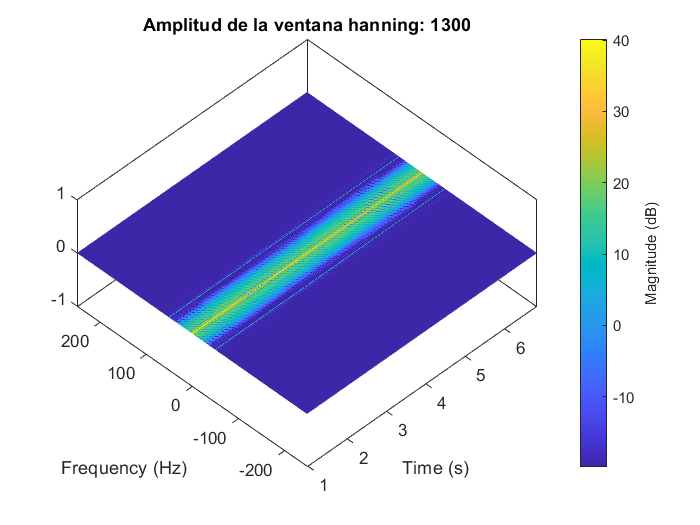


figure
stft(ecg,fs,'Window',hann(winSizes(3)),'FFTLength', winSizes(3));
title("Amplitud de la ventana hanning: " + string(winSizes(3)));
view(-45,65)

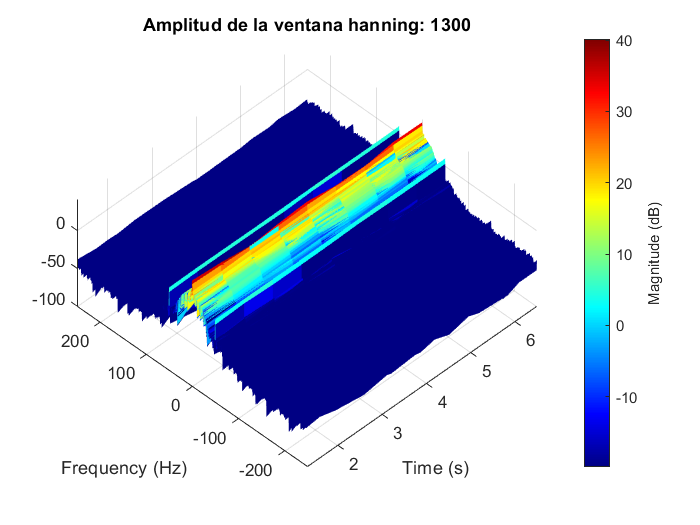

colormap jet

Además la banda de mayor intesidad respecto al espectro de frecuencia está entre los 0 Hz  y 20 Hz, cosa que coincide con el rango frecuencial del complejo QRS de la señal ECG, este complejo es el de picos más altos.

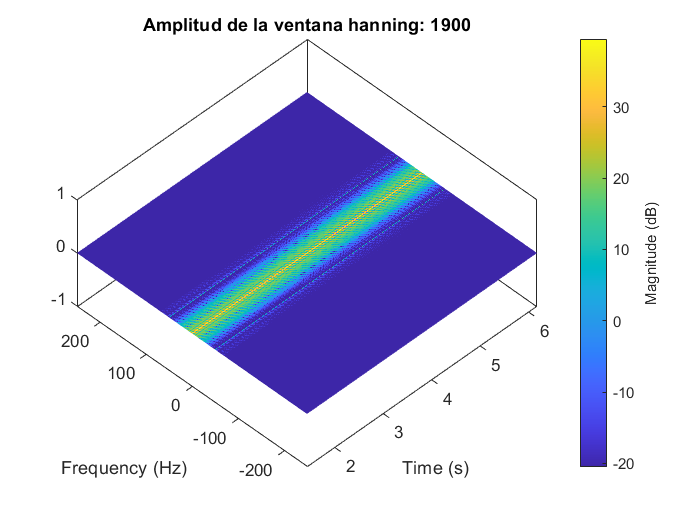

figure
stft(ecg,fs,'Window',hann(winSizes(4)),'FFTLength', winSizes(4));
title("Amplitud de la ventana hanning: " + string(winSizes(4)));
view(-45,65)

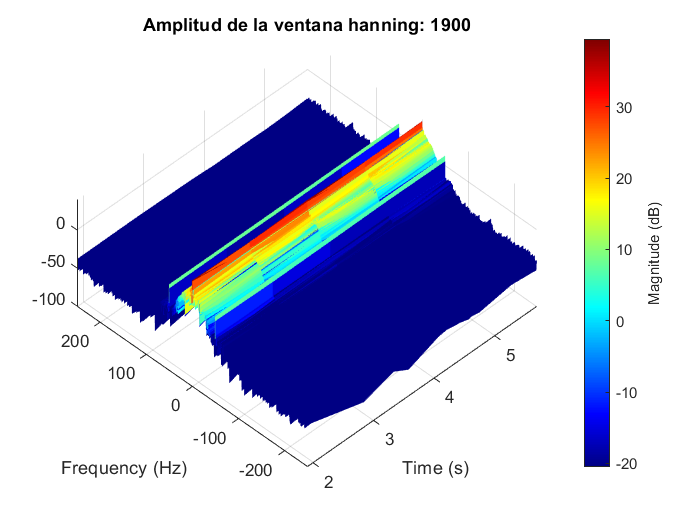

colormap jet

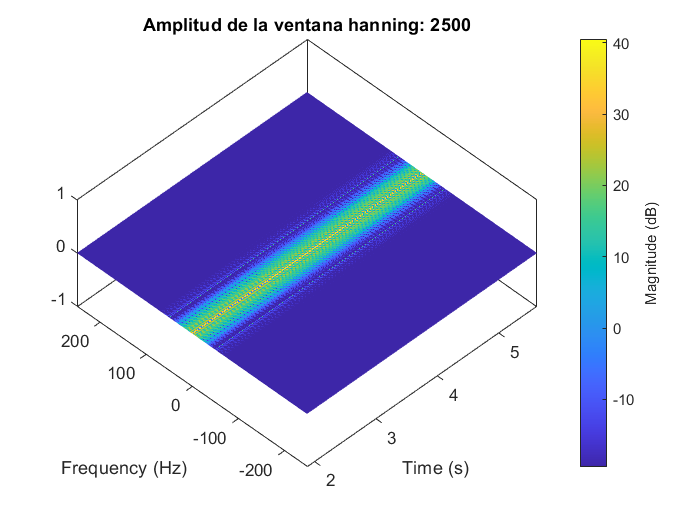

figure
stft(ecg,fs,'Window',hann(winSizes(5)),'FFTLength', winSizes(5));
title("Amplitud de la ventana hanning: " + string(winSizes(5)));
view(-45,65)

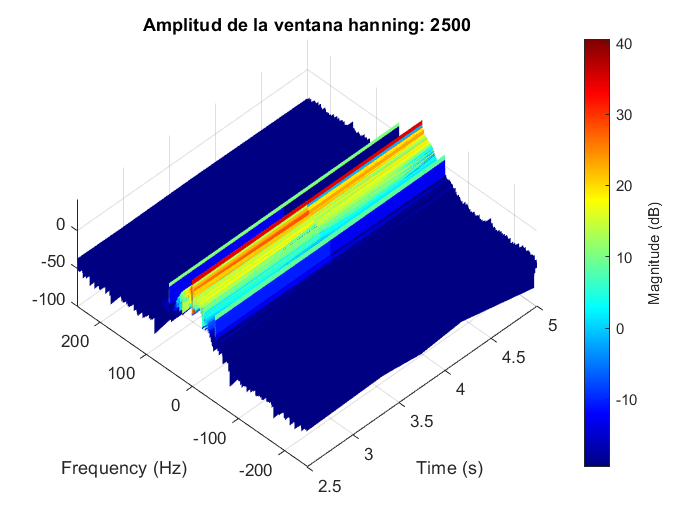

colormap jet